# **Numerical Differentiation **

## Example Problem

Estimate the velocity and acceleration from datasets of position of an object.

clear all

t = 0:0.2:4;
y = [-5.87 -4.23 -2.55 -0.89 0.67 2.09 3.31 4.31 5.06 5.55 5.78 5.77 5.52 5.08 4.46 3.72 2.88 2.00 1.10 0.23 -0.59];

A simple two-point differentiation can be used :

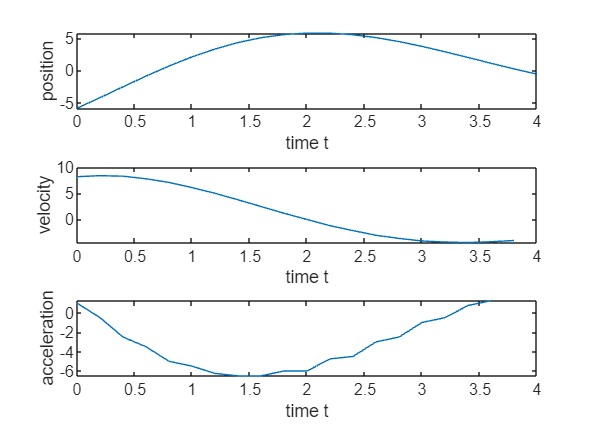

% asusume evenly spaced h
h=0.2;
vel = diff(y)./h;
acc = diff(y,2)./h^2;

%acc = diff(diff(y));
tv=t(1:length(vel));
ta=t(1:length(acc));

figure
subplot (3,1,1)
    plot(t,y)
    xlabel('time t')
    ylabel('position')

subplot (3,1,2)
    plot(tv,vel)
    xlabel('time t')
    ylabel('velocity')

subplot (3,1,3)
    plot(ta,acc)
    xlabel('time t')
    ylabel('acceleration')

## Differentiation Formula

## 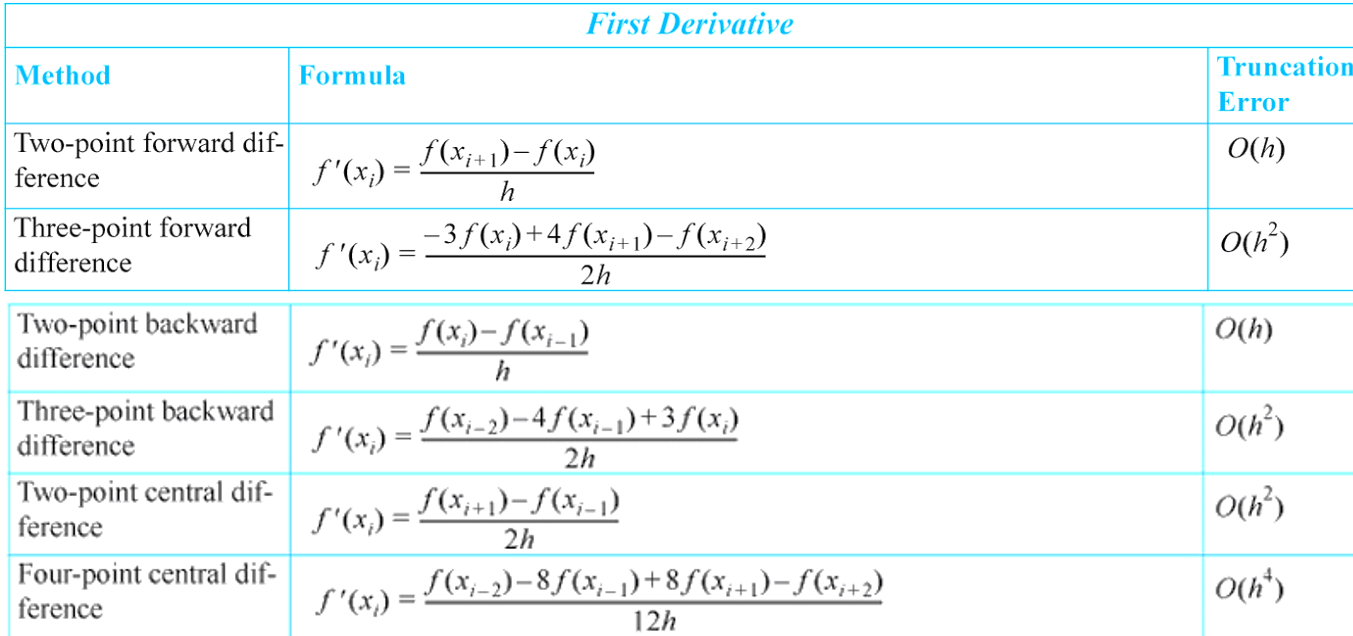

## Exercise

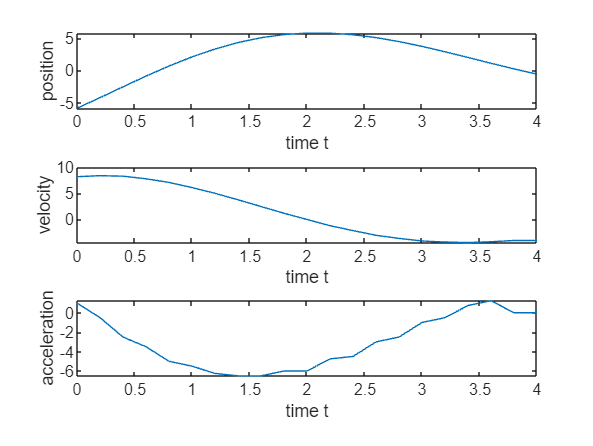

vel = derivative(t,y);
acc = derivative(t,vel);

figure
subplot (3,1,1)
    plot(t,y)
    xlabel('time t')
    ylabel('position')

subplot (3,1,2)
    plot(t,vel)
    xlabel('time t')
    ylabel('velocity')

subplot (3,1,3)
    plot(t,acc)
    xlabel('time t')
    ylabel('acceleration')

## Exercise 1

Create derivative1d(x,y) that returns numerical differentiation  

- Use two-point forward for the first data to the secon-last point

- Use two-point backward for the last data point

- This has the truncation error O(h).  

- In the assignment, you will modify it to have O(h^2) error. 

The function `derivative` can be designed simply as

function dydt = derivative(t,y)
% The derivative: using two-point forward difference formula
% except the last data points. 
    % t와 y의 계수 같은 지 호가인 lengh
    m = length(t);
    dydt=zeros(1,m);
       
    % NOTE: 
    % * MATLAB index is  y(1) to y(m). 
    % * C-Prog index is  y[0] to y[m-1]. 

    % Two-point forward difference 
    for i=1:m-1    
        % [TO-DO Exercise]
        % Hint:  dydt(1)=(y(2)-y(1))/(t(2)-t(1));    
        dydt(i) = (y(i+1)-y(i))/(t(i+1)-t(i));        
    end    

    % Two-point backward for the last point    
    % [TO-DO Exercise]
    dydt(m)=(y(m)-y(m-1))/(t(m)-t(m-1));
end

